# 12. Modeling the LM317 Controller

© B. Rasnow 2 June 25

## Objective 

Model the Arduino controlled voltage regulator circuit we've build. At first, I didn't think this was worthwhile, but it isn't terribly hard -- and can test and reinforce our understanding. What PWM value should we simulate? How about all of them ;-)! 

I already soldered the circuit which makes it difficult to measure some resistor values without disconnecting them from their circuits. There could be parallel resistances e.g., inside the LM317. If flipping the polarity of the ohmmeter changes the measurement, you know there are parallel diodes, e.g., in the transistors or ICs. A DMM measures resistance by applying a small voltage (hopefully below $V_f$ of any diodes and transistors so their impedances will be very high, and insignificant. Always remember to measure resistances with the circuit unpowered, including ensuring no power comes from active PWM pins or other sources.

We'll continue using Arduino software `oscope1.ino`, which responds to two ASCII commands: `p <pwmValue=0-255> analogWrite`'s to output pin D5, and the `b` command returns 1602 bytes consisting of 400 sequential measurements of A0 and A1 appended with the microseconds it took to make those measurements. MATLAB's `oscope2.m `script initializes a serial connection to the Arduino, creates a run button in a figure window, and supports a simple oscilloscope (or spectrum analyzer) display, as was demonstrated earlier. Because `oscope` is implemented as a script, the Arduino is accessible from the command window enabling interactive as well as scripted control. 

## Modeling the LM317 controller in MATLAB

A good approach to modeling anything is start simple. Make assumptions that simplify the model, even if they're a little wrong. If you're lucky, the simple model captures key aspects and it may not even be necessary to replicate more characteristics. Because of inherent complexity, your first model will likely be horrendously wrong, due to all sorts of bugs -- typographic errors, inconsistent units, and more fundamental logical bugs. These are easier to find and fix in simple models. Once debugged, you're in a better place to add additional complexity to include second order terms and corrections. You also can compare models to quantify each 2nd order effects. In a metaphor, add the spices one at a time to the soup, and taste it before adding the next one. You might be satisfied and call it done without having to dice and saute the onions ... 

### Parameters and measurements

Start by defining some key parameters. Just the first ones are used in the first model, but additional parameters were added to the bottom of the list for subsequent models, thereby keeping all parameters in this block. 

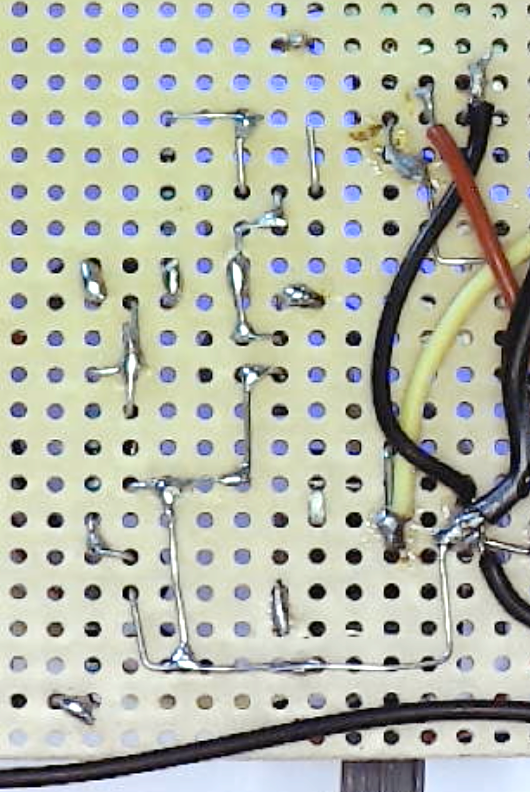 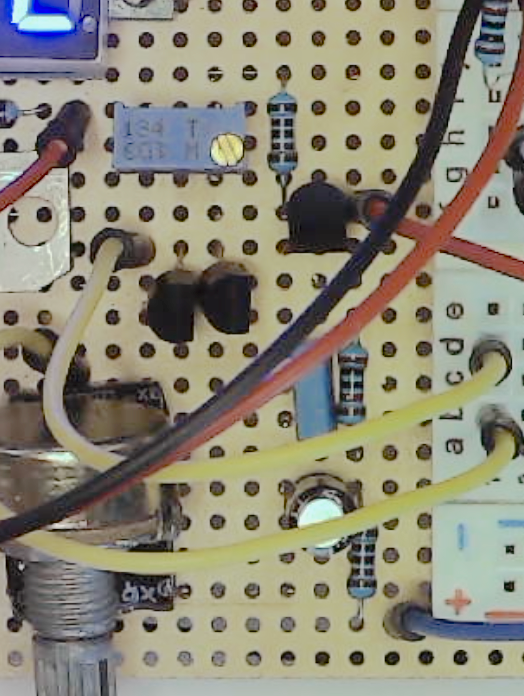 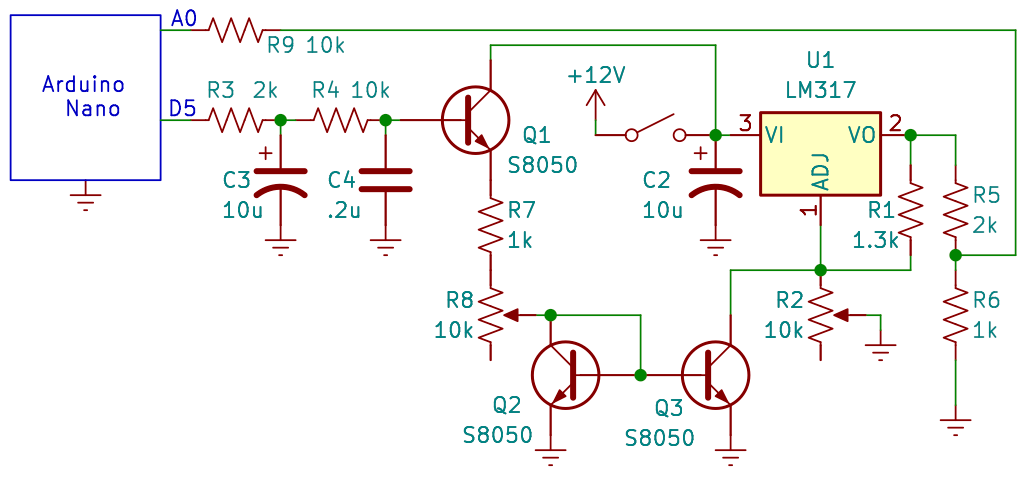        

Figure 1. LM317 controller photos of back and front of board and schematic.

%% parameters -- measure all R's with power OFF
pwm = (50:5:255)'; % PWM values at D5
vref = 4.752; % volts on vref pin
vref317 = 1.252; % measured with R2 at minimum
Vmax = 11.12; % measured maximum voltage out
R1 = 1215; % ohms measured between LM317 pins 1&2 (power off)
R2 = 9.57e3; % ohms measured at maximum
% NOTE: best to measure R2 between the center and UNCONNECTED 
% pin with knob at MINIMUM -- i.e., measuring the other side, 
% eliminating parallel current path inside the LM317
R7 = 3448; % ohms = R7 + R8, measured from Q1 emitter to Q2
% or T3 base (middle pin)
Vbe = 0.56; % estimated transistor B-E voltage when turned on

Load your calibration measurements to compare with the model. You should have saved vectors `pwm` and `v317` in a file called `pwmcaldata.mat` in the previous chapter. This may make finding the file easier for you:

if ~exist('v317','var')
    try
        load pwmcaldata.mat 
    catch
        disp('find file: pwmcaldata.mat')
        [fname, path] = uigetfile('.mat',"find pwmcaldata");
        load([path fname]);
        clear path fname
    end
    disp('successfully loaded measurements')
end

There are many ways to describe a model, but let's try just using MATLAB code and some comments. I generally try to write "self-documenting" code and minimize comments. Too many times I've come across inconsistent code and comments, like this simplified line: 

If you read the executable part, you'd know exactly what it does. But the comment causes you to freeze. Where is the bug? Should the 3 be a 2? Most likely an earlier version (when the comment was written) executed a = b * 2, but the code evolved and the comment didn't. In a Darwinian sense, evolutionary pressure drives code towards improvement, but comments aren't tested, bugs in comments are "neutral", and they tend to persist or grow. Erroneous comments are more disruptive than no comments, so I recommend minimizing comments, keeping them general vs. specific (e.g., in the example above, `% a is rescaled b` might remain valid for longer), but best is to write self-evident or self-documenting executable code. 

### Model 1

Follow the signal from D5 in the schematic as you read the code below. E.g., the low pass filter (to first order) turns the pwm value into a dc voltage at T1's base, as stated in the first two lines. 

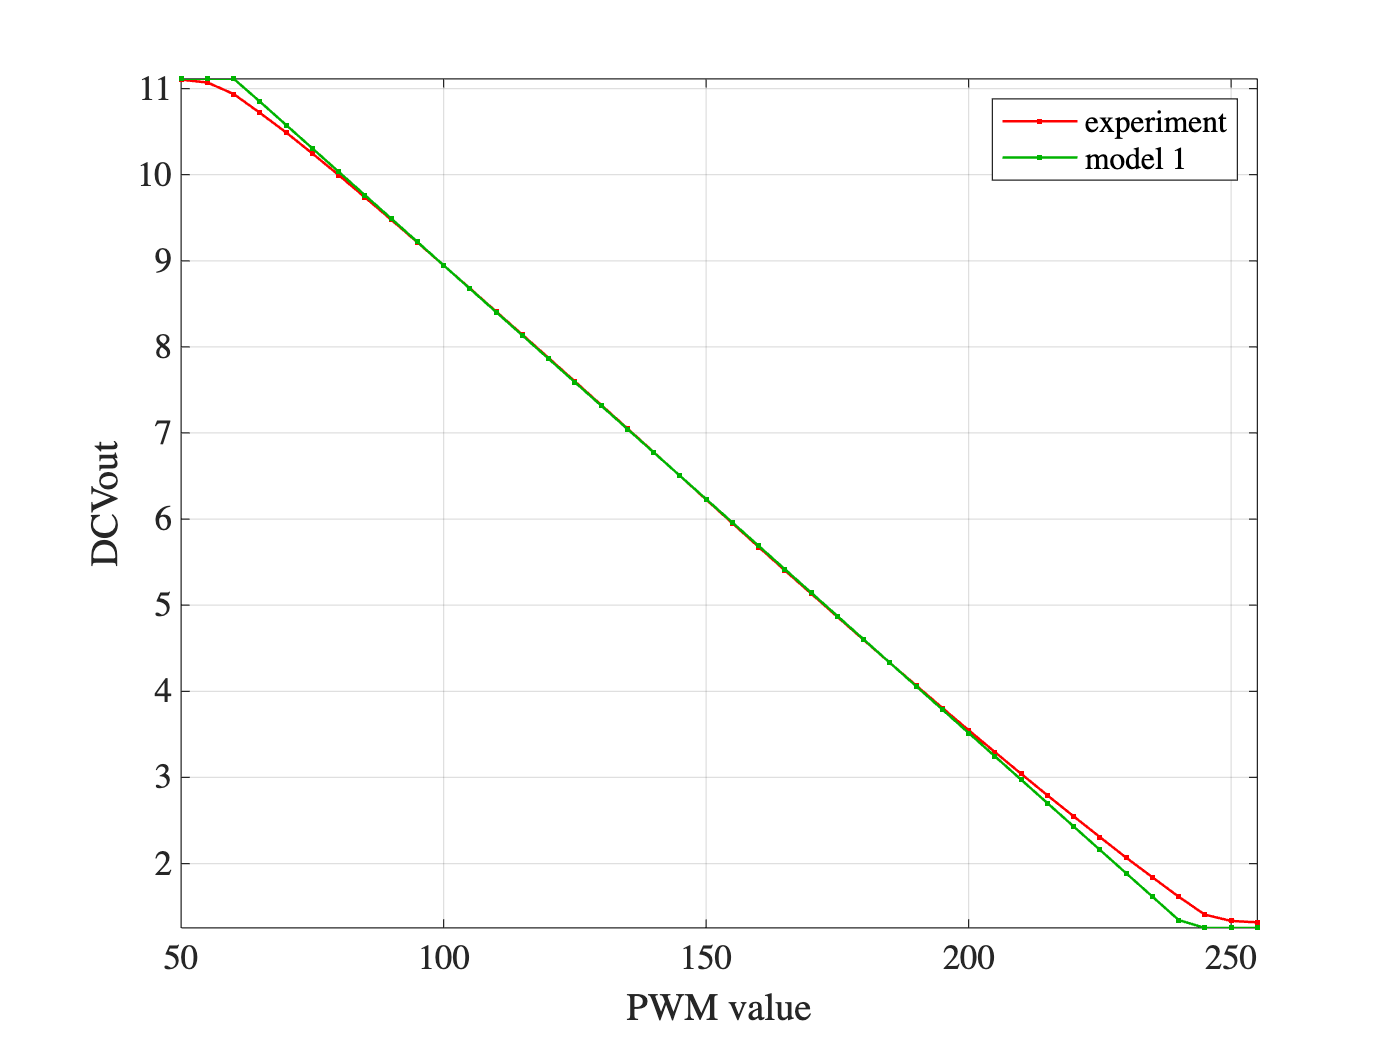

vpwm = pwm * vref / 255; % DC voltage on pin D5 AND base of Q1
Q1baseVoltage = vpwm; % the PWM filter's gain = 1 at DC
Q1emitterVoltage = Q1baseVoltage - Vbe; 
% when Q2 is active, the collector will be close to ground ...
Q2collectorVoltage = Vbe; % because its connected to base
iMirror = (Q1emitterVoltage-Q2collectorVoltage) / R7; % Amps
% if Q1 isn't conducting then iMirror = 0:
iMirror(Q1baseVoltage < Vbe + Q2collectorVoltage) = 0; 
iR1 = vref317 / R1; % Amps, from LM317 datasheet. 50uA from iADJ
fudge = 1.05;
iMirror = iMirror * fudge;
iR2 = iR1 - iMirror; % KCL says iR1 = iR2 + iMirror
VR2 = iR2 * R2; 
DCVout = VR2 + vref317; 
% the output is always less than input voltage - dropout voltage
DCVout(DCVout > Vmax) = Vmax; 
DCVout(DCVout < vref317) = vref317; % Vmin
DCVout1 = DCVout; % rename it so we don't overwrite it later
figure; plot(pwm, [v317 DCVout1]);
xlabel('PWM value'); ylabel('DCVout');
dots; grid; axis tight;
legend('experiment', 'model 1')

        Figure 2. Model 1 vs. measurements.

Reasonable (?) agreement with experiment. We were able to model  thresholds where the circuit behavior changes (e.g., saturation) using inline logic, i.e., `DCVout(DCVout > Vmax) = Vmax`; and `iMirror(Q1baseVoltage < 0.6 + Q2collectorVoltage) = 0; `instead of more verbose `if/else` constructs show the power of MATLAB's syntax. This is a very different modeling approach than conventional circuit simulation programs like SPICE, Eagle, KICAD, etc., where most component parameters and rules are "under the hood". They (sometimes) give accurate results, but offer less intuition about how and why the circuit works than our few code lines above. We didn't model every component, e.g., the PWM filter doesn't appear ... because we're only modeling DC behavior and at DC the capacitors are infinite impedance = 1/(1j*2*pi*0Hz*C). 

This model is yet another tool to explore and test the circuit. E.g., want to see the effects of changing a resistor's value, then change its parameter and run the code again ... With several quick "drylab" iterations, you can improve the fit between model and experiment, which may point you towards rechecking some of your measured parameter values. 

Is it unethical to fudge data and models to fit each other? Not if we are both honest and transparent about what the goals are, which in this case is to better understand how/why our circuit works. What does a non-unitary fudge factor tell us? In this case, that $x$ mA of `iMirror` produces `fudge`*$x$ mA of shunt current from R1. Wouldn't that happen if $\beta_{Q3}/\beta_{Q2}$= `fudge`? So the fudged model suggests that our two transistors have mismatched betas of order `fudge`, which maybe quite plausible.

Should we expect this model to exactly fit the data? Definitely not. (Note: Richard Feynman famously said, paraphrasing, "A theory should not agree with all the measurements, because not all the measurements are correct."). In this case we *know* this model is wrong. Transistors don't instantly turn on when $V_{BE} = 0.6V$. LM317's $I_{ADJ}$ $\ne 0$, as modeled. Q1's base current causes an iR voltage drop across the PWM filter resistors that was ignored, the list could go on. Important is that we captured the circuit's main characteristic behaviors without adding all those extra seasonings to the soup. The simpler model independently confirms that we didn't somehow get lucky with the circuit (as rare as such luck is), but its underlying principles are sound. 

Let's quantitatively explore some of the secondary factors mentioned in the previous paragraph.

### Model 2: Adding transistor beta

$1/\beta$ of Q1's emitter current, `iMirror`, comes from its base, through R3 and R4 of the PWM filter. Fig. 3 shows simplified equivalent circuits relating D5 current to `iMirror`.  Modeling DC behavior lets us ignore the PWM filter capacitors, as their DC impedances to ground are infinite. When Q1 and Q2 are active, their two $V_{BE}$ junctions are equivalent to 600mV batteries. And the current gain of Q1 can be modeled by simply multiplying $R_E$ by $\beta$ (why emitter followers are sometimes called "transimpedance amplifiers"). You might be tempted to use the relationship, $I_B$ = `iMirror` / $\beta$, but the `iMirror` we computed ignored the loading effect we're now trying to model now, so it's also unknown. Combining the two $V_{BE}$ since they are in series, and all the series resistances lets us model Q1's $I_B$ by the 3 equivalent circuits. 

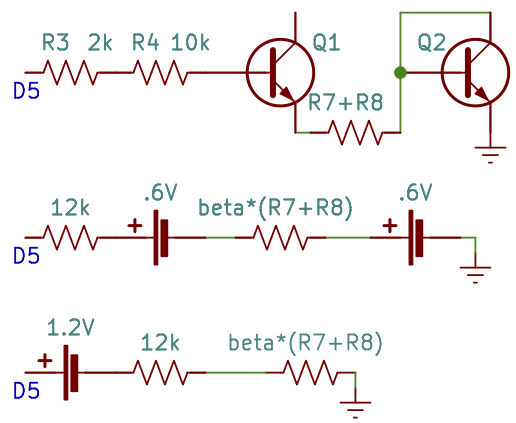

        Figure 3. Equivalent, simplified DC current paths from D5 to ground.

Emitter follower Q1 increases the impedance of its load by $\beta$, so I replaced it by equivalent $V_{BE}$ = 0.6V battery and multipy R7+R8 by $\beta$. D5 > 1.2V when active, so current always flows to the right, and that current should be:

**Model 2 parameters**

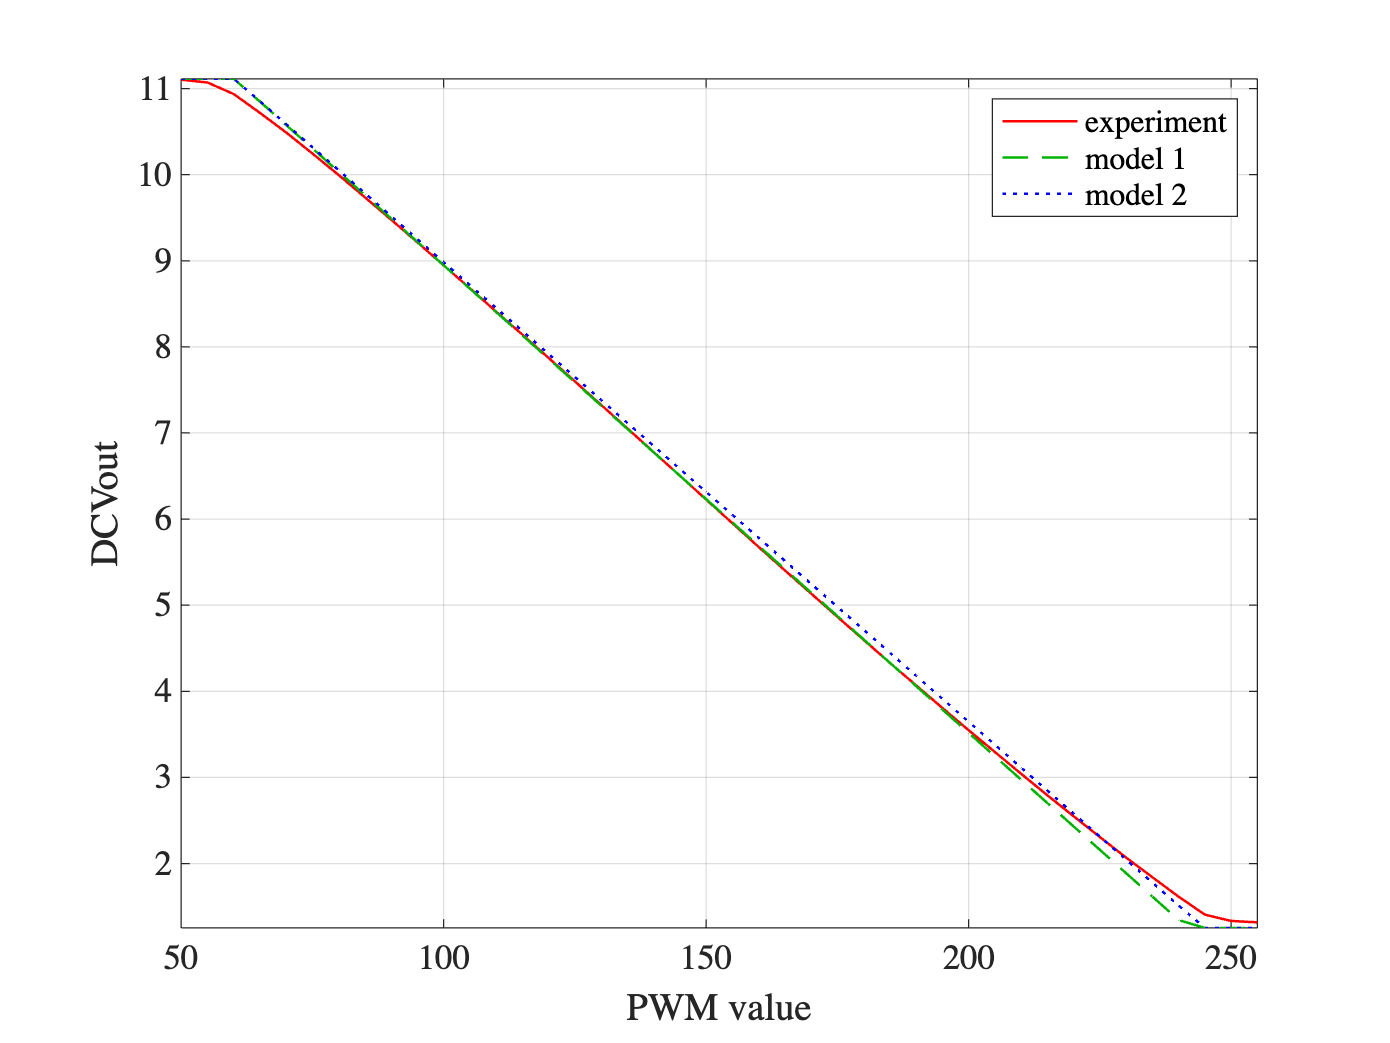

R3 = 12e3; % sum of R3 and R4
beta = 200; % guestimated transistor gain
%% 
Q1emitterCurrent = (vpwm - 2*Vbe) / (R3 + beta * R7);
Q1baseVoltage = vpwm - Q1emitterCurrent * R3; 
% the rest of the model stays the same
Q1emitterVoltage = Q1baseVoltage - Vbe; 
Q2collectorVoltage = Vbe;  
iMirror = (Q1emitterVoltage-Q2collectorVoltage) / R7; % A
% if Q1 isn't conducting then iMirror = 0:
iMirror(Q1baseVoltage < Vbe + Q2collectorVoltage) = 0; 
iR1 = vref317 / R1; % A, from LM317 datasheet. 50uA from iADJ
iMirror = iMirror * fudge;
iR2 = iR1 - iMirror; % KCL says iR1 = iR2 + iMirror
VR2 = iR2 * R2; 
DCVout = VR2 + vref317; 
% the output is always less than input voltage - dropout voltage
DCVout(DCVout > Vmax) = Vmax; 
DCVout(DCVout < vref317) = vref317; % Vmin
DCVout2 = DCVout; % rename it so we don't overwrite it later
h = plot(pwm, [v317 DCVout1 DCVout2]);
xlabel('PWM value'); ylabel('DCVout');
grid; axis tight;
legend('experiment', 'model 1','model 2')
h(2).LineStyle='--'; h(3).LineStyle = ':';

        Figure 4. Finite transistor gain moves slope closer to measurement.

### Model 3: Adding ADJ current

We've thus far ignored current from LM317's $I_{ADJ}$, so let's add this parameter to the model. The datasheet says this can be up to $50\mu A$, but is typically ~20$\mu A$. The code below recycles parameters from Model 1 and 2 that aren't affected by adding $I_{ADJ}$. The first term affected is iR2, which increases by $I_{ADJ}$:

## Model 3 parameters

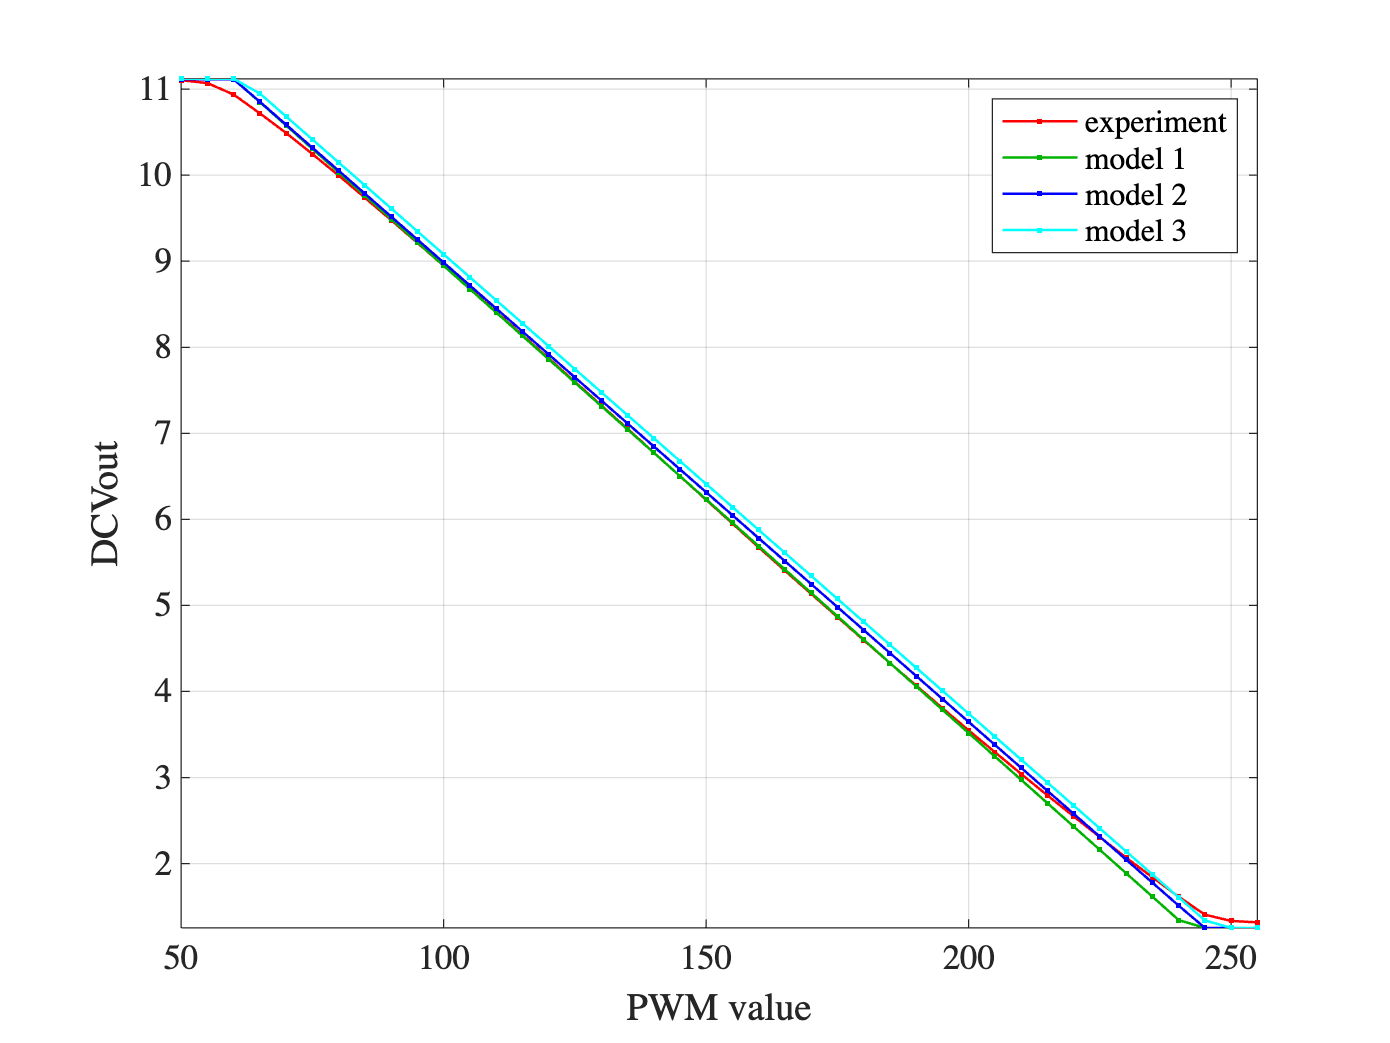

clf;
iAdj = 10e-6; % LM317 ADJ pin current est. from datasheet
%% 
iR2 = iR1 + iAdj - iMirror; % KCL says iR1 = iR2 + iMirror
VR2 = iR2 * R2; 
DCVout = VR2 + vref317; 
% the output is always less than input voltage - dropout voltage
DCVout(DCVout > Vmax) = Vmax; 
DCVout(DCVout < vref317) = vref317; % Vmin
DCVout3 = DCVout; % rename it so we don't overwrite it later
plot(pwm, [v317 DCVout1 DCVout2 DCVout3]);
xlabel('PWM value'); ylabel('DCVout');
dots; grid; axis tight;
legend('experiment', 'model 1','model 2','model 3')

        Figure 5. Comparison of 3 models (after parameter tweaking) and measurements.

### Difference plot

A difference plot provides much better ability to compare the models. Plotting the differences between models and measurements is somwhat akin to rotating Fig. 5 so its slope is horizontal. I also changed the x-axis to vout -- what we care about. 

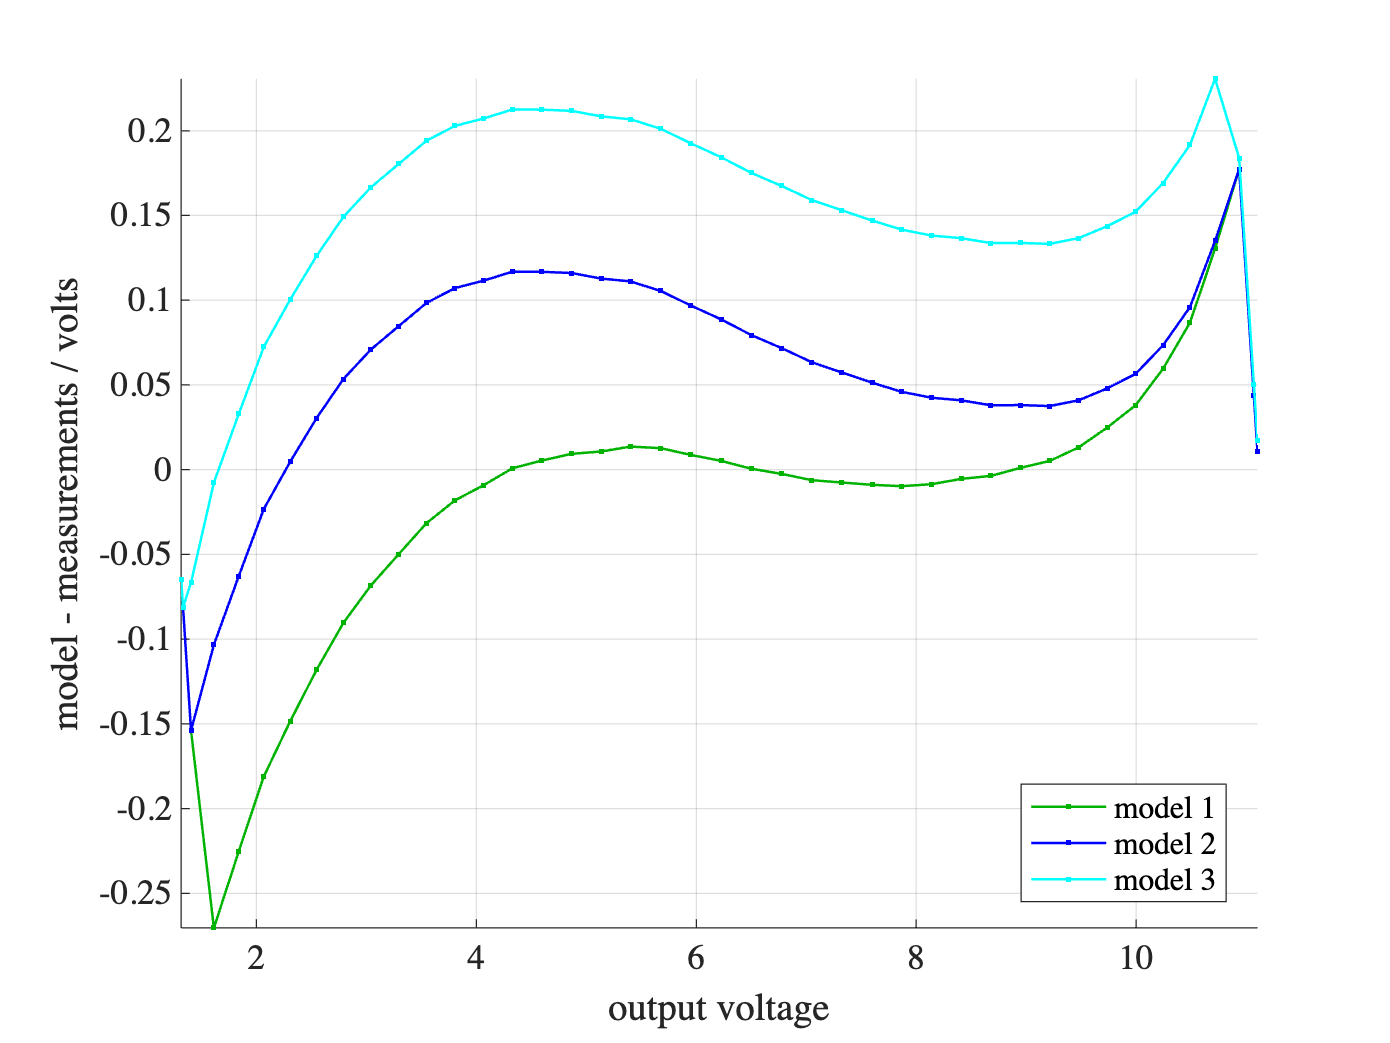

clf;  % clear figure window
set(gca,'ColorOrderIndex',2) % make the first plot green
hold on; % necessary to hold ColorOrderIndex
plot(v317, [DCVout1 DCVout2 DCVout3] - v317);
xlabel('output voltage'); ylabel('model - measurements / volts');
dots; grid; axis tight;
legend('model 1','model 2','model 3','location','best')

        Figure 6. Error vs. output voltage for the 3 models.

rms([DCVout1 DCVout2 DCVout3] - v317)

ans =     0.0858    0.0843    0.1576


iADJ = $10\mu A$ pushed the curve in Fig. 5 to the right and *increased* the rms error. Run this section again with other iADJ estimates -- what do you think is the most likely value of iADJ and is that reasonable?

## What if the mirror's $\beta$'s are mismatched? 

I measured 3 transistors using methods in Chapter 7 and found $\beta = [208.1\  276.4 \ 212.0]$ -- widely variable -- `std(beta) = 38`, coefficient of Variance (CV = `std(beta)/mean(beta)` = 16.5%. Repeating measurements on the same transistor gave the same result with CV < 0.005 = 0.5%. The measurements are all repeatable and also substantially different between transistors -- so it's very likely Q2 and Q3 have different $\beta$'s. They have the same $V_B$ and $V_E$ in the circuit, which means they have the same $i_B$. So each transistor's $i_C$ = $\beta_{[1,2]} i_B$, and $i_{C1} / i_{C2} = \beta_1/\beta_2$. Adjusting pot $R_8$ sets $i_{C1} = (V_{ref}-.6V) / R_8$, so $i_{C2} = (V_{PWM}-.6)\beta_2 / (\beta_1 R_8) = k_1V_{PWM}+k_2$ where $k_1 = R_8\beta_2/\beta_1$is adjusted (via pot $R_8$) for the desired slope that takes into account whatever the mismatch of the transistor's $\beta$'s are. In other words, any mismatch of the $\beta$'s is compensated for simply by adjusting $R_8$. 

## Modeling a multi-stage audio intercom system

Switching gears, let me show you a first-principles model of an audio intercom system for an access control/security system. Inside and outside a remote gate are two electret microphones (and speakers, not shown) and a buzzer -- like a door bell. The first op-amp (left) amplifies (DC gain = R31/R27 = 20) and filters the microphone signal. The second amp has gain~2 and mixes the buzzer and microphone signals. The third stage has gain ~ 1.5 and mixes the two intercom boxes (inside and outside the gate) with audio output from a Raspberry pi computer, who plays jingles indicating when the gate is left open and announces other events by injecting sound snippets into the intercom signal. Every input has an RC high pass filter, and every feedback has an RC low pass filter, that together make 4 stages of bandpass filter with steep transitions. The code below models the gain of each stage and the system gain, and is plotted along with manual measurements made using a function generator providing sine wave input and AC voltmeter measuring output.  

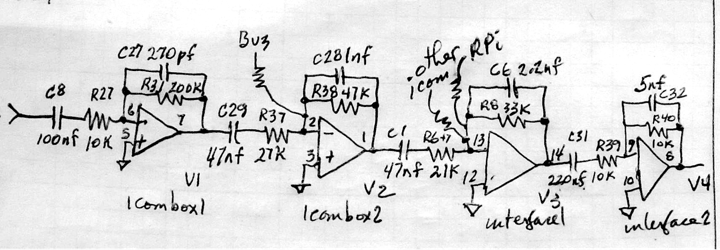

        Figure 7. 4 stage audio amplifier/mixer/filter for an intercom system. 

The model uses the `zc` (Chapter 9) and `zp` (Chapter 10) functions that compute impedances of capacitors and parallel impedances, to compute gains at all frequencies for each op-amp stage in one line: 

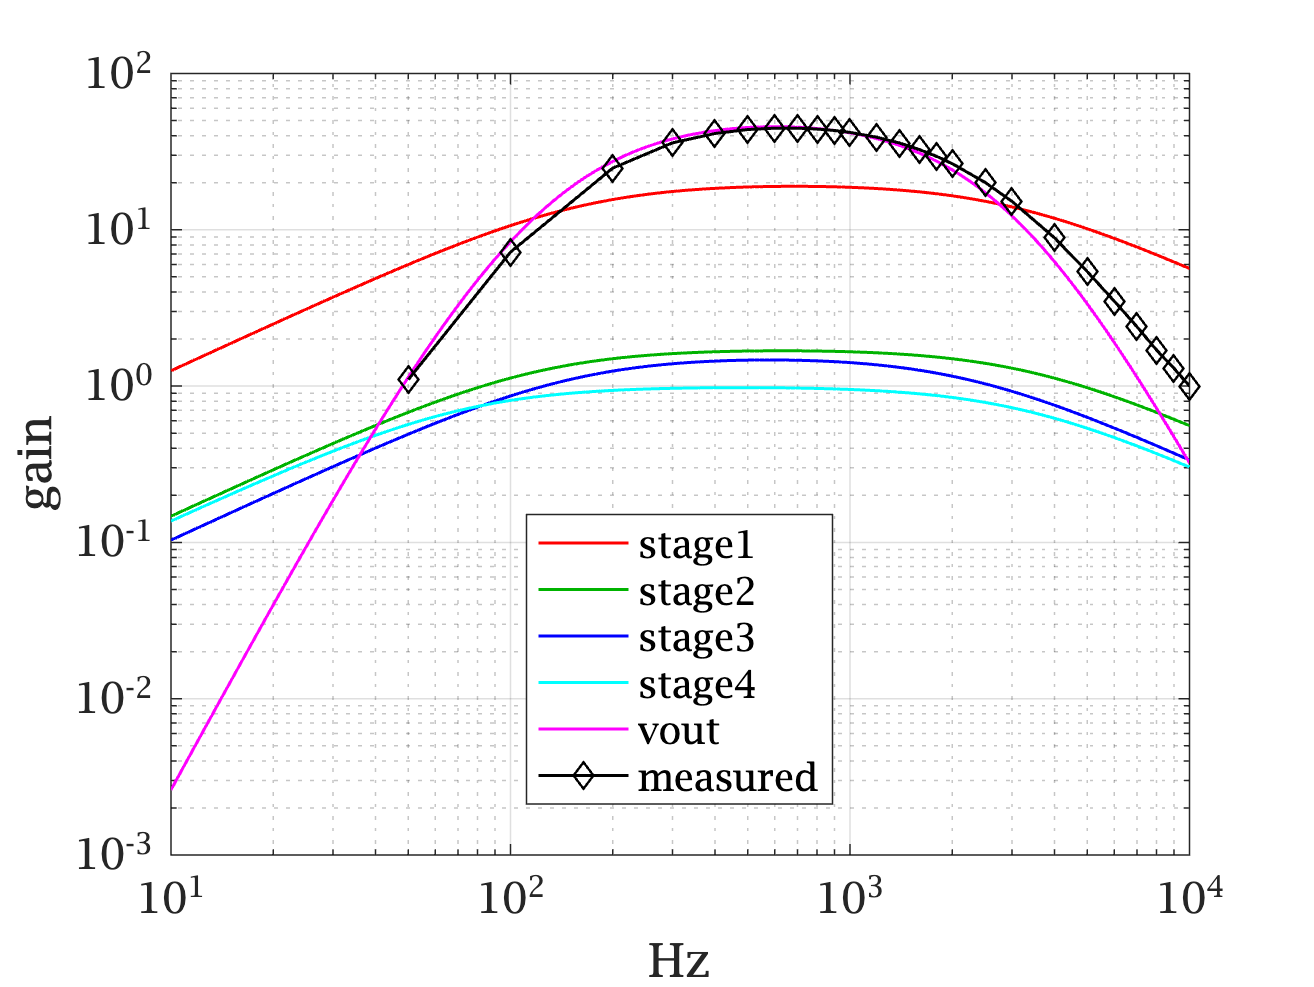

figure;
ff = logspace(1,4,200)'; % frequencies
% first stage of microphone amp
r31 = 200e3; c27 = 270e-12;
r27=10e3; c8 = 100e-9;
gain1 = zp(r31, zc(c27,ff)) ./ (r27+zc(c8,ff)); % = zfeedback/zinput
% 2nd stage of microphone amp
c29 = 50e-9; r37 = 27e3; 
r38 = 47e3; c28 = 1e-9; 
gain2 = zp(r38,zc(c28)) ./ (r37+zc(c29));
% interface 1
r6 = 21e3; c1 = 50e-9;
r8 = 33e3; c6 = 2.2e-9;
gain3 = zp(r8, zc(c6)) ./ (r6 + zc(c1));
% interface 2
r39 = 10e3; c31 = 220e-9;
r40 = 10e3; c32 = 5e-9;
gain4 = zp(r40, zc(c32)) ./ (r39+zc(c31));
% 4 stages together
vout = gain1 .* gain2 .* gain3 .* gain4;

loglog(ff, abs([gain1 gain2 gain3 gain4 vout]))
grid; xlabel('Hz'); ylabel('gain');
legend('stage1','stage2','stage3','stage4','vout', ...
    'location','best');
%% manually measured vrms, with Siglent SDG2042X function 
% generator and Tektronix DM511 DVM
hold on; 
vin = 10; % mVrms measured at mic input
freq = [50 100:100:1000 1200:200:2000]';
von14rms = [21 69 160 200 227 236 239 241 239 236 232 222 210 197 184 170]';
freq2 = [2500 3000:1000:10000]';
von14rms = [11 72 248 360 413 438 447 447 441 432 420 391 359 326 295 265 ]';
von142 = [201 152 89 54 35 24 17 13 10]';
loglog([freq; freq2], [von14rms; von142]/vin,'d-k')
legend('stage1','stage2','stage3','stage4','vout', 'measured','location','best')
hold off;

        Figure 8. Frequency domain simulation and measurements of the circuit in Fig. 7.

The measurements suggest a low pass filter corner was much higher and directed inquiry that revealed C31 was erroneously 50nf instead of 220nf. The system achieves 50% attenuation at 172Hz & 2-2.3kHz and 99% attenuation at ~40Hz and ~20kHz. This reduces hiss & airplane noise and improves hearing voices over truck engines, footsteps over birds, etc. 

## Discussion

With minor (and plausible) parameter fudging, the models agree with measurements, suggesting the initial model captured the primary characteristics of the circuit. I pursued models 2 and 3 because we can learn from doing them academically, but they mainly revealed their respective effects are minor. The models disagree most near the lowest and highest voltages, just where the transistors are transitioning to their active region, or the LM317 is approaching saturation. Nothing in our models attempts to capture realistic device behaviors around these inflection points, so there's no surprise that errors arise here. 

We could attempt to model transistors in their transition regions -- there are many sources for the equations (e.g., [https://en.wikipedia.org/wiki/Bipolar_junction_transistor#Theory_and_modeling).](https://en.wikipedia.org/wiki/Bipolar_junction_transistor#Theory_and_modeling).) But my goal as an engineer is not to add more significant figures, rather its to build devices exhibiting robust and predictable behaviors. These models give me additional confidence that this circuit is robust, and can be expected to keep working tomorrow and onward.

Another key lesson of this activity is to show you not to fear building circuit simulations in MATLAB starting from first principles. Although specialized circuit simulator software such as SPICE and Simulink's electronics toolboxes have powerful capabilities, they can also obfuscate (hide) the dominant and secondary sources of the circuit's characteristics. Here little was hidden from view, the parameters and interactions are all explicit. 

When a complex system like this circuit is empirically measured, and numerically modeled, and the two complicated sets of results agree, confidence in both the measurements and models increases. If they disagree, then one or both are likely wrong. Progress in science and engineering advances much faster when our measurements and models agree. Confronted with a new question, we can turn to the easiest of the two for an answer. Progress in modeling drives improvements in measurements and visa versa. In Fig. 8, without a model (magenta), would I have realized just from the measurements (black) that a component (in a low pass filter) had the wrong value?

What other lessons did  you learn?